# **Dynamics of Planar Mechanisms - Lab Work 1**

## Group Members:

- Ng'ethe Bernice         ENM221-0085/2017

- Vivian Mwangi            ENM221-0163/2017

- Dickson Mutura          ENM221-0082/2017

A four bar linkage is required to generate the following function, θ4 = 65 + 0.43θ2 for 150 ≤ θ2 ≤ 1650 . Where θ2 and θ4 define the rotation angles of the input and output links respectively. It is further required that the length of the fixed link be 410mm. 

Write a computer program in MATLAB to:

 (a) Evaluate the link lengths ratios K1, K2 and K3 using three precision points, and hence determine the lengths of the other links. Use Chebyshev’s spacing. Determine the transmission angles for the given range of input angles and at an increment of 50 , and plot the variation of the transmission angles with the input angles. Comment on the quality of transmission of the linkage. 

(b) Evaluate the link lengths ratios K1, K2 and K3 using the least square method for five precision points, and hence determine the length of the other links. Use Chebyshev’s spacing

(c) Calculate the structural errors throughout the given range of input angles and at an increment of 50 for the two cases in (a) and (b). Plot the variation of the structural errors as a function of the input angles for the two cases and in the same axis. Comment on the results.

% N.B. all angles are in degrees 
% For reference, theta in this context is used to represent input angle(s)
% while phi is used to reperesent output angle(s) unless otherwise indicated
% the limits of 'x' are also in degrees
x0 = 15;      % lower limit of 'x'
xn1 = 165;    % upper limit of 'x'
n = 3;        % number of precision points
theta = chebyshev_spacing(x0, xn1, n) 

theta =    25.0481   90.0000  154.9519



phi = 65 + 0.43.*theta % phi here is obatined using the function defined in the question

phi =    75.7707  103.7000  131.6293


% create a matrix for the 3 simultaneous equations that are formed
% by substituting the 3 pairs of input-output angles obtained above
% into Freudenstein's equation

% 'A' is a 3X3 matrix containing coeficients on the LHS of the equations
A = [cosd(phi(1)) -cosd(theta(1)) 1;     
     cosd(phi(2)) -cosd(theta(2)) 1;     
     cosd(phi(3)) -cosd(theta(3)) 1]

A =     0.2458   -0.9060    1.0000
   -0.2368         0    1.0000
   -0.6643    0.9060    1.0000


 
% 'B' is a 3X1 matrix containing values on the RHS of the equations     
B = [cosd(theta(1))*cosd(phi(1)) + sind(theta(1))*sind(phi(1));
     cosd(theta(2))*cosd(phi(2)) + sind(theta(2))*sind(phi(2));
     cosd(theta(3))*cosd(phi(3)) + sind(theta(3))*sind(phi(3))]

B =     0.6331
    0.9715
    0.9183


% get link ratios and assign them to K1, K2, K3
K = linsolve(A,B) 

K =    -7.1003
   -3.4091
   -0.7101



K1 = K(1)

K1 = -7.1003

K2 = K(2)

K2 = -3.4091

K3 = K(3)

K3 = -0.7101

% Getting the lengths of the links as per the Freudenstein's equation
% All values are in mm
d = 410         % fixed link - value was predefined in the question

d = 410

a =- d/K1       % Input link

a = 57.7438

c =- d/K2       % output link

c = 120.2679

b = sqrt(a^2 + c^2 + d^2 - (K3*2*a*c))   % coupler link

b = 442.4493

## Transmission angle

input_angle = 15:5:165    % create an array of angles, spaced 5 deg apart

input_angle =     15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165



% obtain transmission angles using the formula below
mu = acosd(((b^2 + c^2) - (a^2 + d^2) + (2*a*d*cosd(input_angle))) / (2*b*c))

mu =    37.4156   38.5028   39.8501   41.4268   43.2018   45.1447   47.2269   49.4222   51.7067   54.0590   56.4597   58.8912   61.3376   63.7842   66.2171   68.6235   70.9909   73.3074   75.5614   77.7413   79.8360   81.8342   83.7248   85.4971   87.1401   88.6436   89.9975   91.1925   92.2198   93.0718   93.7417



min_mu = min(mu)    % get minimum transmission angle

min_mu = 37.4156

max_mu = max(mu)    % get maximum transmission angle

max_mu = 93.7417

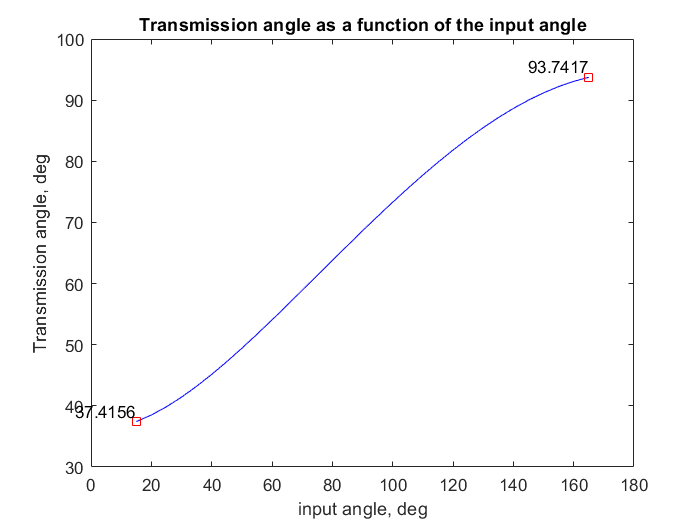

% plot transmission angle against input angle

plot(input_angle,mu,'b-')
hold on 

plot(input_angle(1), mu(1),'rs') % add square markers at the beginning and end of plot
hold on 

plot(input_angle(end), mu(end),'rs') % add max and min values of transmission angles to the plot
x = [input_angle(1) input_angle(end)];
y = [mu(1) mu(end)];
labels = {min_mu,max_mu};
text(x,y,labels,'VerticalAlignment','bottom','HorizontalAlignment','right')
hold off

title('Transmission angle as a function of the input angle')

xlabel('input angle, deg')
ylabel('Transmission angle, deg')

The ideal transmission angle should be between 40 and 140 degrees. From our plot and calculations, our transmission angles start at 37.4 to 93.7 deg. The lower limit is less than 3 degrees below the ideal 40 degrees, while the upper limit is well within the ideal limit. Hence ensuring an almost smooth operation.

nb = 5;     % number of precision points

% call Chebyschev function to get the precision points
theta_b = chebyshev_spacing(x0, xn1, nb) 

theta_b =    18.6708   45.9161   90.0000  134.0839  161.3292


phi_b = 65 + 0.43.*theta_b

phi_b =    73.0284   84.7439  103.7000  122.6561  134.3716


% create a matrix for the 5 simultaneous equations that are formed
% by substituting the 5 sets of input-output angles obtained above
% into Freudenstein's equation

% 'Ab' is a 5X3 matrix containing coeficients on the LHS of the equations
Ab = [cosd(phi_b(1)) -cosd(theta_b(1)) 1;     
      cosd(phi_b(2)) -cosd(theta_b(2)) 1;     
      cosd(phi_b(3)) -cosd(theta_b(3)) 1;
      cosd(phi_b(4)) -cosd(theta_b(4)) 1;
      cosd(phi_b(5)) -cosd(theta_b(5)) 1;]

Ab =     0.2919   -0.9474    1.0000
    0.0916   -0.6957    1.0000
   -0.2368         0    1.0000
   -0.5396    0.6957    1.0000
   -0.6993    0.9474    1.0000



% 'Bb' is a 5X1 matrix containing coeficients on the RHS of the equations      
Bb = [cosd(theta_b(1) - phi_b(1));
      cosd(theta_b(2) - phi_b(2));
      cosd(theta_b(3) - phi_b(3));
      cosd(theta_b(4) - phi_b(4));
      cosd(theta_b(5) - phi_b(5))]

Bb =     0.5827
    0.7790
    0.9715
    0.9802
    0.8913


 
Kb = lsqr(Ab,Bb)  % principle of least squares

lsqr converged at iteration 3 to a solution with relative residual 0.091.


Kb =    -1.7293
   -0.7061
    0.4632



Kb1 = Kb(1)

Kb1 = -1.7293

Kb2 = Kb(2)

Kb2 = -0.7061

Kb3 = Kb(3)

Kb3 = 0.4632

% Getting the lengths of the links as per the Freudenstein's equation
% All values are in mm
d_b = 410         % fixed linked- value was predefined in the question

d_b = 410

a_b =- d/Kb1       % Input link

a_b = 237.0898

c_b =- d/Kb2       % output link

c_b = 580.6619

b_b = sqrt(a^2 + c^2 + d^2 - (Kb3*2*a*c))   % coupler link

b_b = 423.6332

## Structural error analysis

output_angle = 65 + 0.43.*input_angle % get a range of output angles from the given input angles

output_angle =    71.4500   73.6000   75.7500   77.9000   80.0500   82.2000   84.3500   86.5000   88.6500   90.8000   92.9500   95.1000   97.2500   99.4000  101.5500  103.7000  105.8500  108.0000  110.1500  112.3000  114.4500  116.6000  118.7500  120.9000  123.0500  125.2000  127.3500  129.5000  131.6500  133.8000  135.9500


 % e_1 represents values obtained from link ratios in part a)
e_1 = (K1*cosd(output_angle)) - (K2*cosd(input_angle) + K3 - cosd(input_angle - output_angle))

e_1 =     2.2968    2.5022    2.6847    2.8445    2.9822    3.0987    3.1949    3.2718    3.3306    3.3727    3.3996    3.4128    3.4140    3.4049    3.3874    3.3633    3.3343    3.3025    3.2696    3.2376    3.2081    3.1830    3.1640    3.1525    3.1502    3.1583    3.1781    3.2108    3.2573    3.3183    3.3946



% e_2 rep's values obtained from link ratios in part b)
e_2 = (Kb1*cosd(output_angle)) - (Kb2*cosd(input_angle) + Kb3 - cosd(input_angle - output_angle))

e_2 =     0.2213    0.3055    0.3838    0.4562    0.5229    0.5838    0.6391    0.6889    0.7335    0.7729    0.8076    0.8376    0.8633    0.8851    0.9032    0.9179    0.9297    0.9388    0.9457    0.9507    0.9541    0.9563    0.9576    0.9584    0.9590    0.9595    0.9605    0.9619    0.9642    0.9675    0.9719


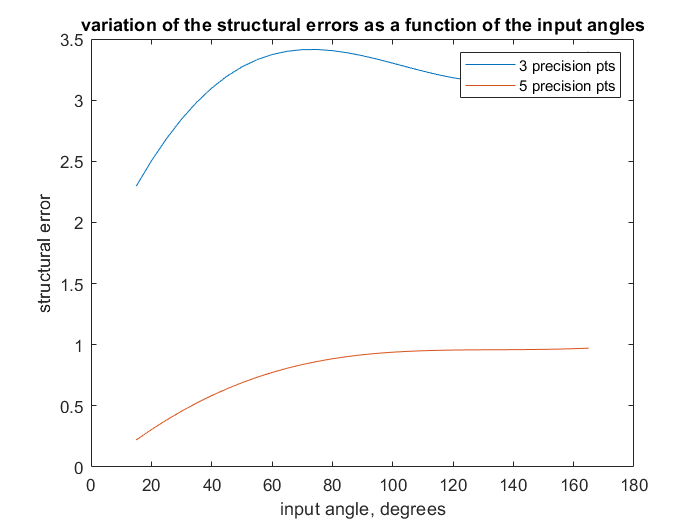

% plot the variation of the structural errors as a function of the input angles
plot(input_angle,e_1)     % structural errors of part a)
hold on

plot(input_angle,e_2)     % strutural errors part b)
hold off

legend('3 precision pts','5 precision pts')
title('variation of the structural errors as a function of the input angles')
xlabel('input angle, degrees')
ylabel('structural error')


disp('From the graph, using Chebyschev spacing with more precision points reduces the error.')

From the graph, using Chebyschev spacing with more precision points reduces the error.


## Chebyschev function definition

function xj = chebyshev_spacing(x0, xn1, n)
    xj = zeros(1,n);
    for i = 1:n
        xj(i) = (0.5*(x0+xn1)) - (0.5*(xn1 -x0)*cos((pi*(2*i -1))/(2*n)));
    end
end
% the function returns xj, which is an array of n precision points